# Trim, Linearise and design Control systems for the 6-dof model:

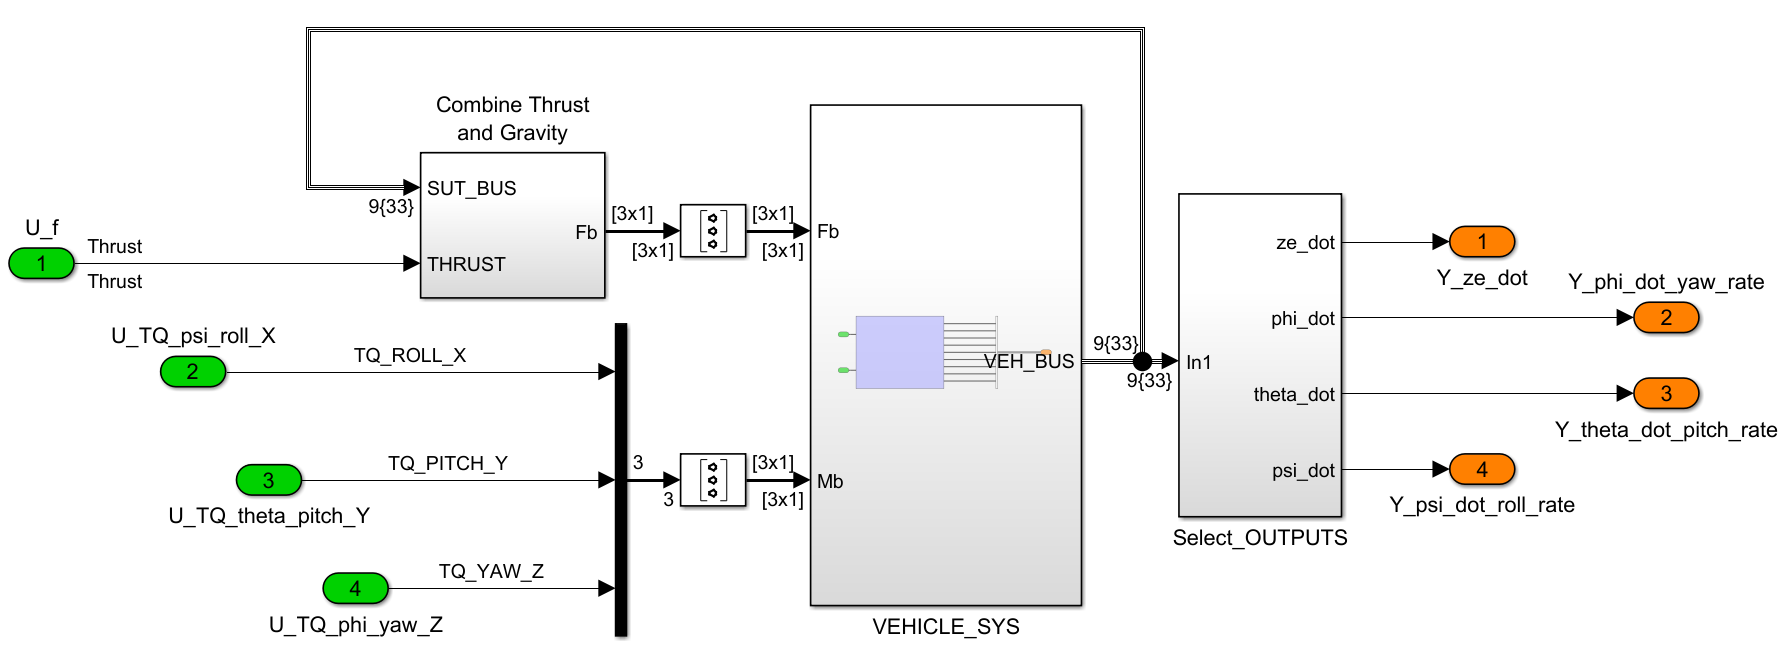

In this task we're going to linearise our 6-DOF **Simulink** vehicle model. We're going to do this because we'd like to apply some "classical" control design techniques in order to design a control system for the vehicle.  And as you know, classical control techniques require a LINEAR plant model.  The workflow that we'll follow is this:

- We'll find an operating point for the vehicle. An operating point is characterized by the state(X), the input(U) and the output(Y).    We'll look specifically for an operating point that corresponds to steady state, ie: where the vehicle's state derivatives are ZERO. This is referred to as finding a **TRIMMED operating point**.

- We'll then use this TRIMMED operating point to calculate a linearised version of the vehicle model.

- Finally, we'll then use this linearised model to design controllers for ALTITUDE, YAW and PITCH control.

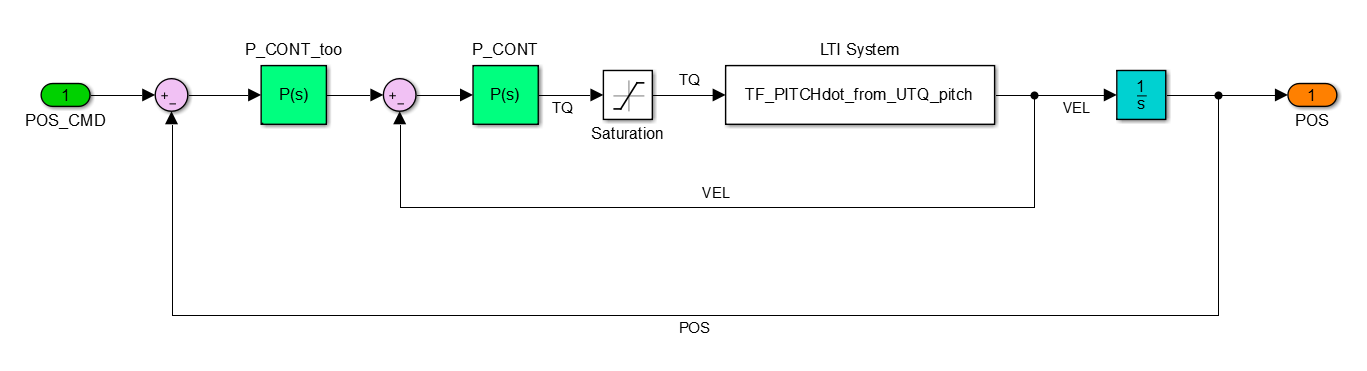

`Bradley Horton : 01-Jun-2016, bradley.horton@mathworks.com.au`

# 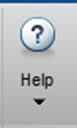 Take a moment !

If you're interested in reading about how to linearize a NON linear plant model.  Use the MATLAB HELP browser and try this simple text search

- `linearize control system`

HINT:  today we'll be using the functions:

- `operspec`

- `findop`

- `linearize`

## Load the model parameters:

bh_quad_params
warning('off')

## Create the operating point specification object.

model  = 'bh_linearise_6dof_multiple_PORTS';
opspec = operspec(model);

In our operating point specification, note the following:

- Our 4 (green) root level INPORT blocks are the system inputs 

- Our 4 (orange) root level OUTPORT blocks are the system outputs 

- Our 12 STATE variable come from our 4 integrator blocks (each integrator block has 3 states)

display(opspec)


 Operating point specification for the Model bh_linearise_6dof_multiple_PORTS.
 (Time-Varying Components Evaluated at time t=0)

States: 
----------
(1.) bh_linearise_6dof_multiple_PORTS/VEHICLE_SYS/bh_6DOF (Euler Angles)/p,q,r 
	 spec:  dx = 0,  initial guess: 0
	 spec:  dx = 0,  initial guess: 0
	 spec:  dx = 0,  initial guess: 0
(2.) bh_linearise_6dof_multiple_PORTS/VEHICLE_SYS/bh_6DOF (Euler Angles)/phi theta psi
	 spec:  dx = 0,  initial guess: 0
	 spec:  dx = 0,  initial guess: 0
	 spec:  dx = 0,  initial guess: 0
(3.) bh_linearise_6dof_multiple_PORTS/VEHICLE_SY

For each of our 12 states we can specify "desired" values for each of the following.  

- `x           :`   initial guess for state value

- `SteadyState :`   a logical indicating we are looking for a dx=0 final value

- `Min         :`   minimum bound for state value

- `Max         :`   maximum bound for state value

For our problem, we're going to look for an operating point where ALL 12 of our states are at SteadyState (ie: dx/dt=0)

[ opspec.States(1).SteadyState, opspec.States(2).SteadyState, opspec.States(3).SteadyState, opspec.States(4).SteadyState ]

ans = 3×4 logical array
   1   1   1   1
   1   1   1   1
   1   1   1   1


Our trimming function(coming up next) will then look for an operating point that satisfies this specification:

## Look for the steady state operating point.

opt           = findopOptions('DisplayReport','off');
[op,opreport] = findop(model,opspec, opt);

Review our trimmed OPERATING point and NOTE the following:

- We have indeed found a steady state operating point because the state derivatives are either zero OR very small $O(10^{-7})$

- To maintain this steady state pose , our THRUST input needs to supply a value of 9.1.  And this makes sense as it counteracts the force appled by gravity ... which is 9.0958 (==P_veh.mass * 9.81)

- In this trimmed pose, ALL of the system outputs are ZERO.

display(opreport)


 Operating point search report for the Model bh_linearise_6dof_multiple_PORTS.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) bh_linearise_6dof_multiple_PORTS/VEHICLE_SYS/bh_6DOF (Euler Angles)/p,q,r 
      x:             0      dx:             0 (0)
      x:             0      dx:             0 (0)
      x:             0      dx:             0 (0)
(2.) bh_linearise_6dof_multiple_PORTS/VEHICLE_SYS/bh_6DOF (Euler Angles)/phi theta psi
      x:             0      dx:             0 (0)
      x:             0      dx:             0 (0)
      x:             0      dx:             0 (0)
(3.) 

## Linearize the model about this operating point:

Next we'll linearise our model about this trimmed operating point:

sys_6dof_lin = linearize(model,op);

First note the names of the INPUTS "U" () and the OUTPUTS "Y" ():

sys_6dof_lin.InputName  

ans = 4×1 cell array
    {'U_f'               }
    {'U_TQ_psi_roll_X'   }
    {'U_TQ_theta_pitch_Y'}
    {'U_TQ_phi_yaw_Z'    }


sys_6dof_lin.OutputName

ans = 4×1 cell array
    {'Y_ze_dot'              }
    {'Y_phi_dot_yaw_rate'    }
    {'Y_theta_dot_pitch_rate'}
    {'Y_psi_dot_roll_rate'   }


And we can use these names to INDEX into our linerised model.  For example:

SOME_TRANSFER_FUNCTION = tf(sys_6dof_lin('Y_theta_dot_pitch_rate', 'U_TQ_theta_pitch_Y'))


SOME_TRANSFER_FUNCTION =
 
  From input "U_TQ_theta_pitch_Y" to output "Y_theta_dot_pitch_rate":
  171.5
  -----
    s
 
Continuous-time transfer function.



# OK, let's look at some transfer functions

 Pay particular attention to the following outputs:

- Y_ze_dot

- Y_phi_dot_yaw_rate

- Y_theta_dot_pitch_rate

- Y_psi_dot_roll_rate

WHY? - because these outputs represent the outputs that we want to control.  You'll also observe that each of these outputs are caused by a single input.

## OUTPUT #1 = Y_ze_dot

 ATTENTION: note how the **Y_ze_dot** output is only dependednt on the **U_f** input

tf(sys_6dof_lin('Y_ze_dot', :))


ans =
 
  From input "U_f" to output "Y_ze_dot":
  1.079
  -----
    s
 
  From input "U_TQ_psi_roll_X" to output "Y_ze_dot":
  0
 
  From input "U_TQ_theta_pitch_Y" to output "Y_ze_dot":
  0
 
  From input "U_TQ_phi_yaw_Z" to output "Y_ze_dot":
  0
 
Continuous-time transfer function.



## OUTPUT #2 = Y_phi_dot_yaw_rate

ATTENTION: note how the **Y_phi_dot_yaw_rate** output is only dependednt on the **U_TQ_phi_yaw_Z **input

tf(sys_6dof_lin('Y_phi_dot_yaw_rate', :))


ans =
 
  From input "U_f" to output "Y_phi_dot_yaw_rate":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_phi_dot_yaw_rate":
  0
 
  From input "U_TQ_theta_pitch_Y" to output "Y_phi_dot_yaw_rate":
  0
 
  From input "U_TQ_phi_yaw_Z" to output "Y_phi_dot_yaw_rate":
  89.38
  -----
    s
 
Continuous-time transfer function.



## OUTPUT #3 = Y_theta_dot_pitch_rate

ATTENTION: note how the **Y_theta_dot_pitch_rate** output is only dependednt on the **U_TQ_theta_pitch_Y **input

tf(sys_6dof_lin('Y_theta_dot_pitch_rate', :))


ans =
 
  From input "U_f" to output "Y_theta_dot_pitch_rate":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_theta_dot_pitch_rate":
  0
 
  From input "U_TQ_theta_pitch_Y" to output "Y_theta_dot_pitch_rate":
  171.5
  -----
    s
 
  From input "U_TQ_phi_yaw_Z" to output "Y_theta_dot_pitch_rate":
  0
 
Continuous-time transfer function.



## OUTPUT #4 = Y_psi_dot_roll_rate

ATTENTION: note how the **Y_psi_dot_roll_rate** output is only dependednt on the **U_TQ_psi_roll_X **input

tf(sys_6dof_lin('Y_psi_dot_roll_rate', :))


ans =
 
  From input "U_f" to output "Y_psi_dot_roll_rate":
  0
 
  From input "U_TQ_psi_roll_X" to output "Y_psi_dot_roll_rate":
  171.5
  -----
    s
 
  From input "U_TQ_theta_pitch_Y" to output "Y_psi_dot_roll_rate":
  0
 
  From input "U_TQ_phi_yaw_Z" to output "Y_psi_dot_roll_rate":
  0
 
Continuous-time transfer function.



# So we can summarise these **TRANSFER FUNCTION** results as:

- 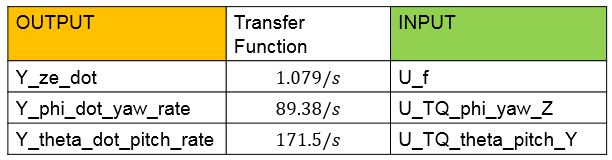

Create the 3 linear plant transfer functions:

TF_ZEdot_from_Uf           = tf(sys_6dof_lin('Y_ze_dot', 'U_f'));
TF_YAWdot_from_UTQ_yaw     = tf(sys_6dof_lin('Y_phi_dot_yaw_rate', 'U_TQ_phi_yaw_Z'));
TF_PITCHdot_from_UTQ_pitch = tf(sys_6dof_lin('Y_theta_dot_pitch_rate', 'U_TQ_theta_pitch_Y'));

## Design dual loop cascade controllers:

Our next task is to design 3 SISO controllers for our 6-DOF vehicle model.  The controllers are:

- Altitude (ie: Z) control

- YAW angle control

- PITCH angle control  (NB: the ROLL controller will be identical)

The design requirements for this task are:

-     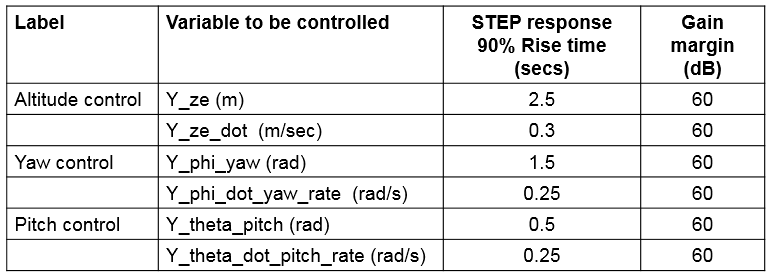

## Our SISO controller structure:

For each of these SISO controllers the structure that we'll use will involve 2 proportional controllers configured in a cascade loop.  The inner loop is the velocity loop and the outer loop is the position loop. This control structure is shown below:

-            

- 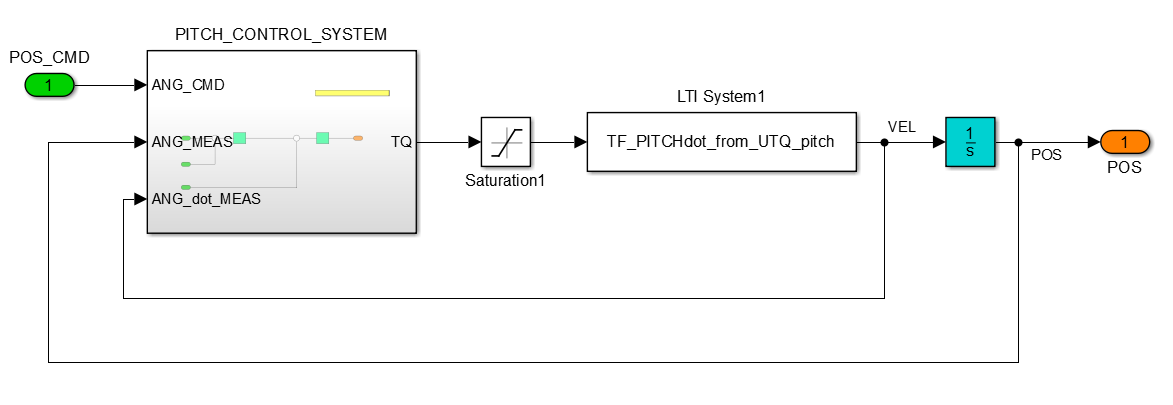

To design each controller we'll design the INNER velocity loop controller first, and then we'll design the OUTER positional controller. 

## Now do the design:

Open the Simulink model `bh_do_CONTROL_DESIGN_via_PID_TUNER.slx` and consider the subsystem called "INITIAL_PITCH_CONTROL_SYSTEM". Launch the PID tuner app for each of the green P blocks and design according to the requirements. NOTE: although all of our designs are just "P-controllers", the tuner app is called the "PID tuner" - hey, no big deal !

open_system('bh_do_CONTROL_DESIGN_via_PID_TUNER.slx')

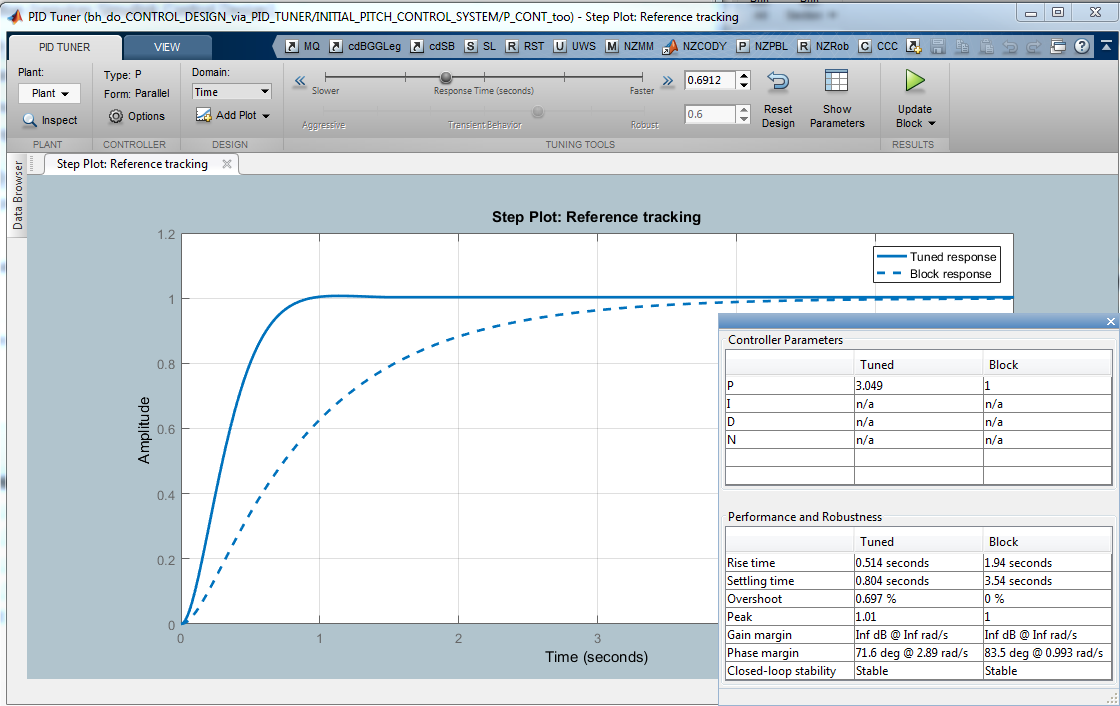

And you can repeat this design for the YAW and ALTITUDE controllers.  The final designs that I have made are also shown in the `bh_do_CONTROL_DESIGN_via_PID_TUNER.slx` model, and they are:

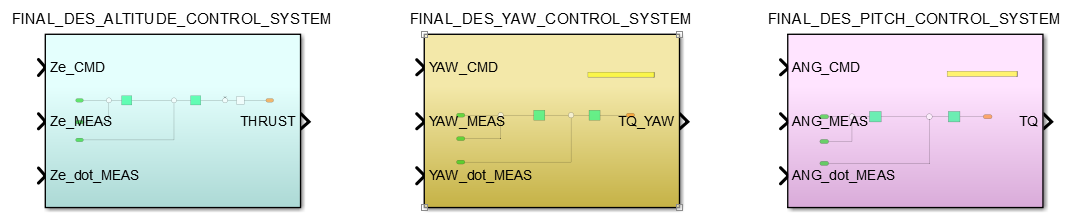

# But what about the NON-linear 6-DOF model ?

The controllers that we've just designed used a linear approximation of our 6-DOF model. SO we now need to try the controllers with our NON-linear model.  Open the model  `bh_test_LINCONT_on_NONLIN_plant.slx` and see how the controllers performed - here we apply STEPS and pulses of:

- Ze = 1 (m)

- Pitch = 30 (degrees)

- YAW = 60 (degrees)

- 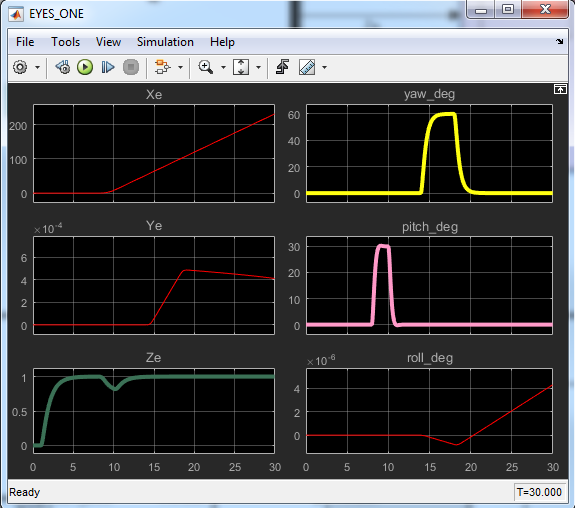

# Recall how these pieces come together in our Quadcopter model: